Ls = [47.94; 36.97; 75.94; 30.88; 45.15; 46.06; 31.82; 42.95; 
    33.12; 35.87; 66.02; 43.82; 40.85; 41.68; 43.82];
Ws = [130.32; 50.91; 639.06; 27.94; 79.84; 109.95; 33.12; 90.02; 
    35.87; 38.09; 365.03; 83.93; 79.84; 83.10; 70.11];
n = length(Ls);

First we plot the data points:

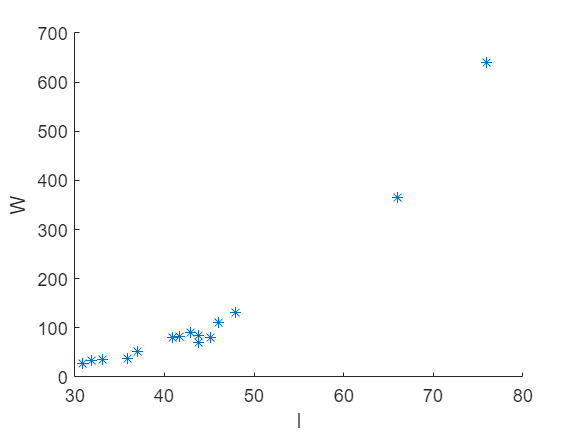

figure;
scatter(Ls, Ws, 'Marker', '*')
xlabel('l')
ylabel('W')

It can be easily observed that l-W seems to be distributed on an exponential curve or quadrate. 

We will test the models and choose the one with the least the root of the average of the residual squared sum.

# Experiment

## (1) Exponential fitting

we can model them using 


$$\hat{W} = c_2e^{c_3 \hat{L}}$$


hence $\ln\hat{W}=\ln  c_2 +c_3\hat{L}$, we can apply $\ln$ on $W$ dimension and do a linear fittng. i.e. to solving 


$$\left\lbrack \begin{array}{cc}
1 & L_1 \\
1 & L_2 \\
\vdots  & \vdots \\
1 & L_n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ln \;c_2 \\
c_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\ln \;W_1 \\
\ln \;W_2 \\
\vdots \\
\ln \;W_n 
\end{array}\right\rbrack$$


in the least square sense, and get $\ln c_2$, $c_3$ , hence the parameter $c_2, c_3$ can be known.

The quality of our fit can be measured by a residual sum


$$E=\sqrt{\sum (W_n-\hat{W}_n)^2/n}$$


A = [ones(n, 1), Ls];
b = log(Ws);

cs = A \ b;
cs(1) = exp(cs(1));

f = @(x) cs(1) .* exp(cs(2) .* x);
hat_Ws = f(Ls);

err = norm(hat_Ws - Ws) / sqrt(n);
err

err = 28.2669

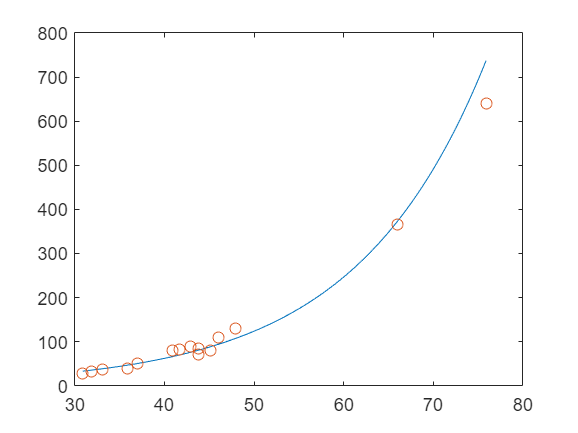


% plot
xs = (min(Ls):0.1:max(Ls))';
ws = f(xs);
figure;
plot(xs, ws);
hold on;
scatter(Ls, Ws);
hold off

## (2) Quadrate exponential fitting

we can model them using 


$$\hat{W} = c_1e^{c_2 \hat{L} + c3 \hat{L}^2}$$


hence $\ln\hat{W}=\ln  c_1 +c_2\hat{L} + c_3\hat{L}^2}$ , we can apply $\ln$ on $W$ dimension and do a linear fittng. i.e. to solving 


$$\left\lbrack \begin{array}{ccc}
1 & L_1  & L_1^2 \\
1 & L_2  & L_2^2 \\
\vdots  & \vdots  & \vdots \\
1 & L_n  & L_n^2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ln \;c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\ln \;W_1 \\
\ln \;W_2 \\
\vdots \\
\ln \;W_n 
\end{array}\right\rbrack$$


in the least square sense, and get $\ln c_1$, $c_2$ , $c_3$ hence the parameters can be known.

The quality of our fit can be measured by a residual sum


$$E=\sqrt{\sum (W_n-\hat{W}_n)^2/n}$$


A = [ones(n, 1), Ls, Ls .^ 2];
b = log(Ws);

cs = A \ b;
cs(1) = exp(cs(1));

f = @(x) cs(1) .* exp(cs(2) .* x + cs(3) .* x .^ 2);
hat_Ws = f(Ls);

err = norm(hat_Ws - Ws) / sqrt(n);
err

err = 10.1198

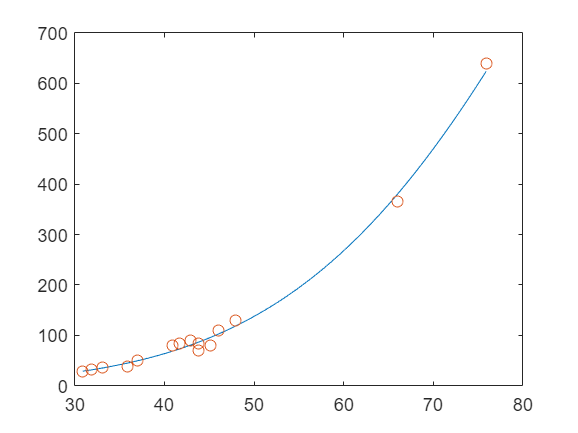


% plot
xs = (min(Ls):0.1:max(Ls))';
ws = f(xs);
figure;
plot(xs, ws);
hold on;
scatter(Ls, Ws);
hold off

## (3) Quadrate fitting

we can model them using 


$$\hat{W} = c_1+c_2\hat{L}+c_3\hat{L}^2$$


then we are to solving 


$$\left\lbrack \begin{array}{ccc}
1 & L_1  & L_1^2 \\
1 & L_2  & L_2^2 \\
\vdots  & \vdots  & \vdots \\
1 & L_n  & L_n^2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\;c_1 \\
c_2 \\
c_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\;W_1 \\
\;W_2 \\
\vdots \\
\;W_n 
\end{array}\right\rbrack$$


in the least square sense, and get $\ln c_1$, $c_2$ , $c_3$ hence the parameters can be known.

The quality of our fit can be measured by a residual sum


$$E=\sqrt{\sum (W_n-\hat{W}_n)^2/n}$$


A = [ones(n, 1), Ls, Ls .^ 2];
cs = A \ Ws;

f1 = @(x) cs(1) + cs(2) .* x + cs(3) .* x .^ 2;
hat_Ws = f1(Ls);

err = norm(hat_Ws - Ws) / sqrt(n);
err

err = 12.3734

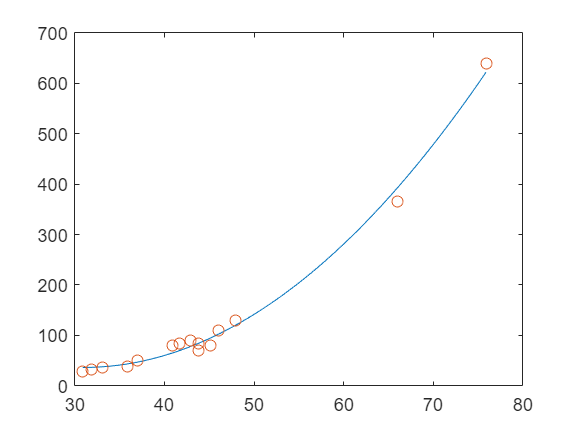


% plot
xs = (min(Ls):0.1:max(Ls))';
ws = f1(xs);
figure;
plot(xs, ws);
hold on;
scatter(Ls, Ws);
hold off

# Result

The second model results is the best. We will choose it and follow the procedure illustrated above.